# Best Subset Selection with fitlm(...,'quadratic') 

fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\Stage 6 Regression Second Try\saved data");
addpath(fpath,dpath);
%load 'Stage 6 Regression Second Try'\'saved data'\regression\Tp_14_sorted.mat
%load 'Stage 6 Regression Second Try'\'saved data'\regression\Tv_13_sorted.mat
%load 'Stage 6 Regression Second Try'\'saved data'\'true values'\h_min_sorted.mat

Store results in structure arrays: bestSubset & tempStruct

**bestSubset**: num_sensors, combination, Tv_model, Tv_MSE, Tp_14_sorted_fitted, Tp_model, Tp_MSE, h_min_fit, Residuals, h_MSE

**tempStruct**:                         combination, Tv_model, Tv_MSE, Tp_14_sorted_fitted, Tp_model, Tp_MSE

for i = 1:13
    C = nchoosek(1:13,i); % 13选 i, 每一行表示一种组合
    bestSubset(i).num_sensors = i;
    
    for j = 1:height(C) % loop through every possible combination for i kept sensors
        idx = C(j,:);
        tempStruct(j).combination = idx;

        % train cross-validated quadratic linear model to predict T_{max}
        [trained_mdl,~,vMSE] = train_Tv_model(Tv_13_sorted,idx);
        tempStruct(j).Tv_model = trained_mdl;
        tempStruct(j).Tv_MSE = vMSE;

        % predict T_max with the trained model
        yfit = trained_mdl.predictFcn(Tv_13_sorted(:,1:end-1));
        yfit = array2table(yfit,"VariableNames","T_value");
        Tp_14_sorted(:,"T_value") = yfit;
        tempStruct(j).Tp_14_sorted_fitted = Tp_14_sorted;

        % train cross-validated quadratic linear model to predict beta_{T_{max}}
        % note: may need to perform Ridge regression
        [trained_mdl,~,vMSE] = train_Tp_model(Tp_14_sorted,idx);
        tempStruct(j).Tp_model = trained_mdl;
        tempStruct(j).Tp_MSE = vMSE;
        
    end

    % select the sensor combination that produces the best prediction of T_max position
    Tp_MSE = zeros(height(C),1);
    for j = 1:height(C)
        Tp_MSE(j) = tempStruct(j).Tp_MSE;
    end
    [~,minIdx] = min(Tp_MSE);

    % 将选中的行填入bestSubset(i)
    bestSubset(i).combination = tempStruct(minIdx).combination;
    bestSubset(i).Tv_model = tempStruct(minIdx).Tv_model;
    bestSubset(i).Tv_MSE = tempStruct(minIdx).Tv_MSE;
    bestSubset(i).Tp_14_sorted_fitted = tempStruct(minIdx).Tp_14_sorted_fitted;
    bestSubset(i).Tp_model = tempStruct(minIdx).Tp_model;
    bestSubset(i).Tp_MSE = tempStruct(minIdx).Tp_MSE;

end

% Calculate h_min_fit, h_MSE, Residuals
h_min_true = h_min_sorted{:,:};
for i = 1:numel(bestSubset)
    mdl = bestSubset(i).Tp_model;
    Tp14_tbl = bestSubset(i).Tp_14_sorted_fitted;
    yfit = mdl.predictFcn(Tp14_tbl(:,1:end-1)); % predicted beta_Tmax
    
    h_min_fit = beta_to_hmin(yfit,120,1.6667,0.25);
    bestSubset(i).h_min_fit = h_min_fit; % h_min_fit

    err = h_min_true - h_min_fit; % h_min_true的顺序对应T_max_positions_sorted的顺序
    bestSubset(i).Residuals = err; % Residuals
    MSE = sum(err.^2)/length(h_min_fit); 
    bestSubset(i).h_MSE = MSE; % h_MSE
end

bestSubset % saved as 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat

bestSubset = 1×13 struct array with fields:
    num_sensors
    combination
    Tv_model
    Tv_MSE
    Tp_14_sorted_fitted
    Tp_model
    Tp_MSE
    h_min_fit
    Residuals
    h_MSE


#### Plot validation MSE & RMSE for all possible number of sensors

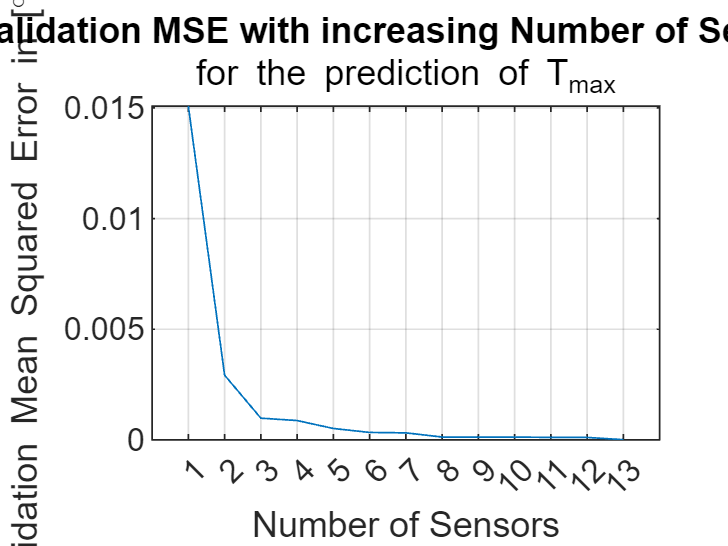

load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat

Tv_MSE = zeros(1,numel(bestSubset));
Tp_MSE = zeros(1,numel(bestSubset));

for i = 1:numel(bestSubset)
    Tv_MSE(i) = bestSubset(i).Tv_MSE;
    Tp_MSE(i) = bestSubset(i).Tp_MSE;
end

% plot MSE for T_max & beta_Tmax
figure
plot(1:13,Tv_MSE), grid on
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Validation Mean Squared Error in [{℃}^2]")
title("Validation MSE with increasing Number of Sensors",...
    "for the prediction of T_{max}")

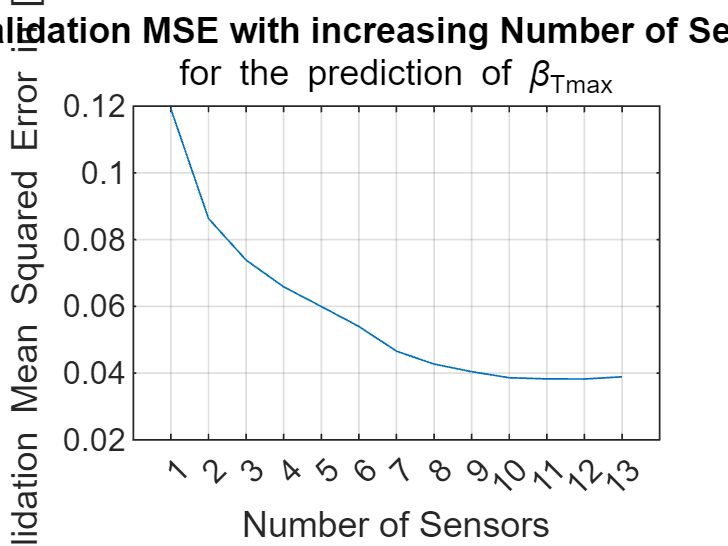


figure
plot(1:13,Tp_MSE), grid on
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Validation Mean Squared Error in [{°}^2]")
title("Validation MSE with increasing Number of Sensors",...
    "for the prediction of \beta_{Tmax}")

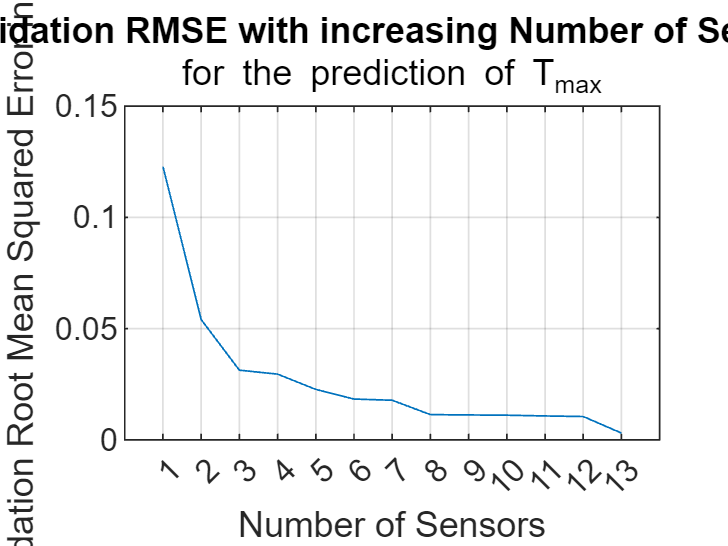


% plot RMSE for T_max & beta_Tmax
figure
plot(1:13,sqrt(Tv_MSE)), grid on
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Validation Root Mean Squared Error in [℃]")
title("Validation RMSE with increasing Number of Sensors",...
    "for the prediction of T_{max}")

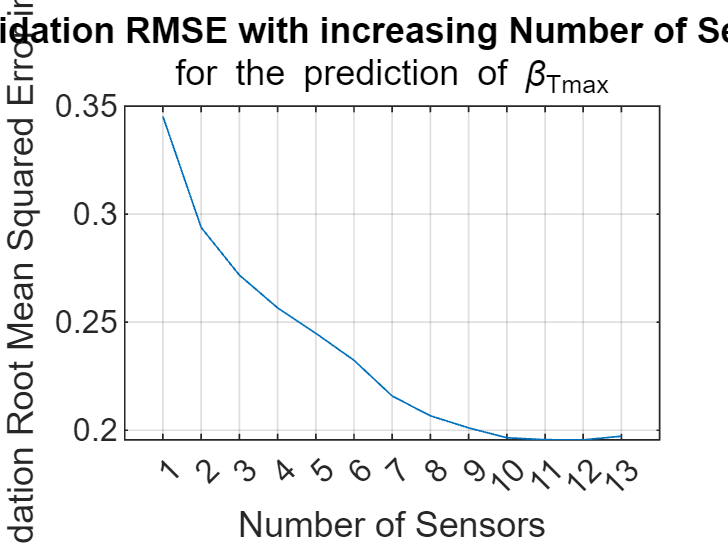


figure
plot(1:13,sqrt(Tp_MSE)), grid on
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Validation Root Mean Squared Error in [°]")
title("Validation RMSE with increasing Number of Sensors",...
    "for the prediction of \beta_{Tmax}")

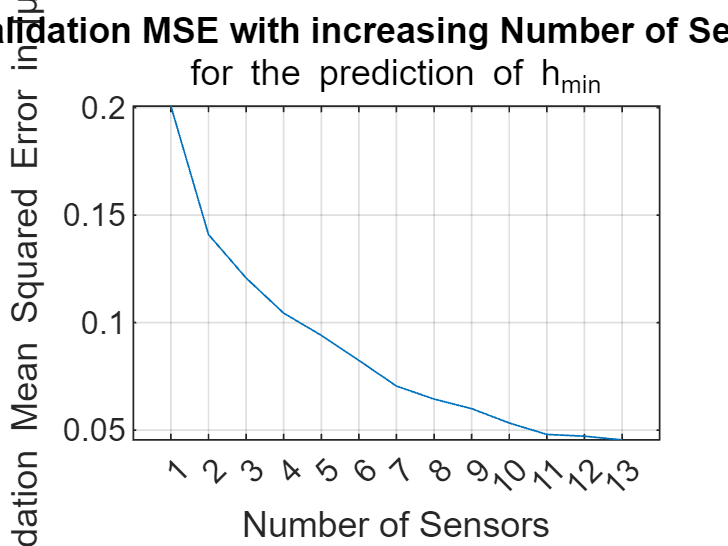


% plot MSE for h_min
h_MSE = zeros(1,numel(bestSubset)); % column vector
for i = 1:numel(bestSubset)
    h_MSE(i) = bestSubset(i).h_MSE;
end

figure
plot(1:13,h_MSE), grid on
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Validation Mean Squared Error in [{μm}^2]")
title("Validation MSE with increasing Number of Sensors",...
    "for the prediction of h_{min}")

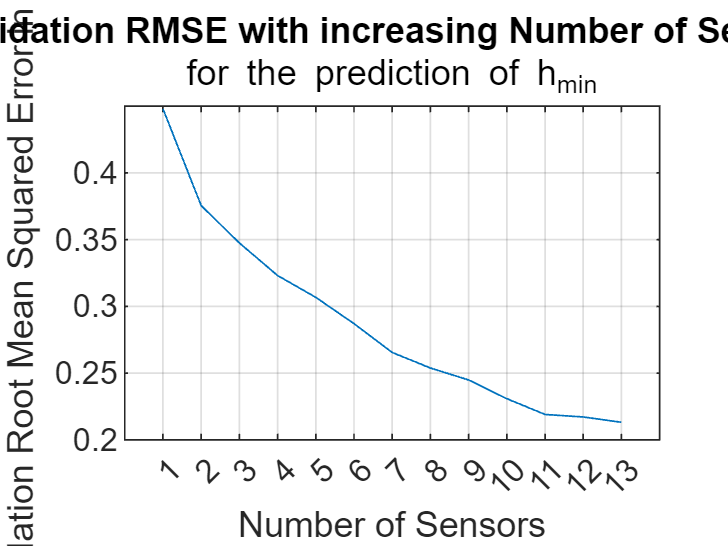


% plot RMSE for h_min
figure
plot(1:13,sqrt(h_MSE)), grid on
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Validation Root Mean Squared Error in [μm]")
title("Validation RMSE with increasing Number of Sensors",...
    "for the prediction of h_{min}")

**Plot in 3x2 tiled layout**

fig = tiledlayout(3,2,"TileSpacing","compact")

fig =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 2]
            Padding: 'loose'
        TileSpacing: 'compact'

  Show all properties


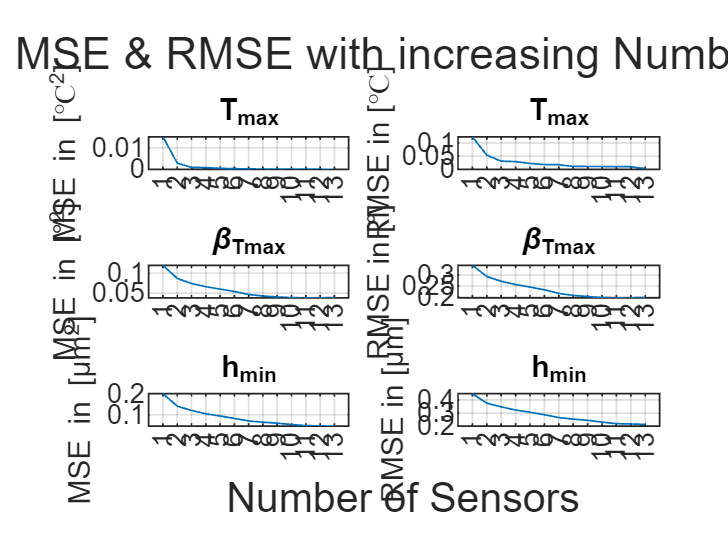

xlabel(fig,"Number of Sensors")
title(fig,"Validation MSE & RMSE with increasing Number of Sensors")

ax1 = nexttile; % MSE T_max
plot(1:13,Tv_MSE), grid on
xticks(1:13), xlim([0,14])
ylabel("MSE in [{℃}^2]")
title(ax1,"T_{max}")

ax2 = nexttile; % RMSE T_max
plot(1:13,sqrt(Tv_MSE)), grid on
xticks(1:13), xlim([0,14])
ylabel("RMSE in [℃]")
title(ax2,"T_{max}")

ax3 = nexttile; % MSE beta_Tmax
plot(1:13,Tp_MSE), grid on
xticks(1:13), xlim([0,14]), ylim([0,Tp_MSE(1)+0.01])
ylabel("MSE in [{°}^2]")
title(ax3,"\beta_{Tmax}")

ax4 = nexttile; % RMSE beta_Tmax
plot(1:13,sqrt(Tp_MSE)), grid on
xticks(1:13), xlim([0,14]),ylim([0,sqrt(Tp_MSE(1))+0.01])
ylabel("RMSE in [°]")
title(ax4,"\beta_{Tmax}")

ax5 = nexttile; % MSE h_min

h_MSE = zeros(1,numel(bestSubset)); % column vector
for i = 1:numel(bestSubset)
    h_MSE(i) = bestSubset(i).h_MSE;
end

plot(1:13,h_MSE), grid on
xticks(1:13), xlim([0,14]), ylim([0,h_MSE(1)+0.01])
ylabel("MSE in [{μm}^2]")
title(ax5,"h_{min}")

ax6 = nexttile; % RMSE h_min
plot(1:13,sqrt(h_MSE)), grid on
xticks(1:13), xlim([0,14]), ylim([0,sqrt(h_MSE(1))+0.01])
ylabel("RMSE in [μm]")
title(ax6,"h_{min}")

linkaxes([ax1 ax3 ax5],'x')
linkaxes([ax2 ax4 ax6],'x')

#### Plot "Accuracy Output" for all possible number of sensors

Number of Sensors: 1


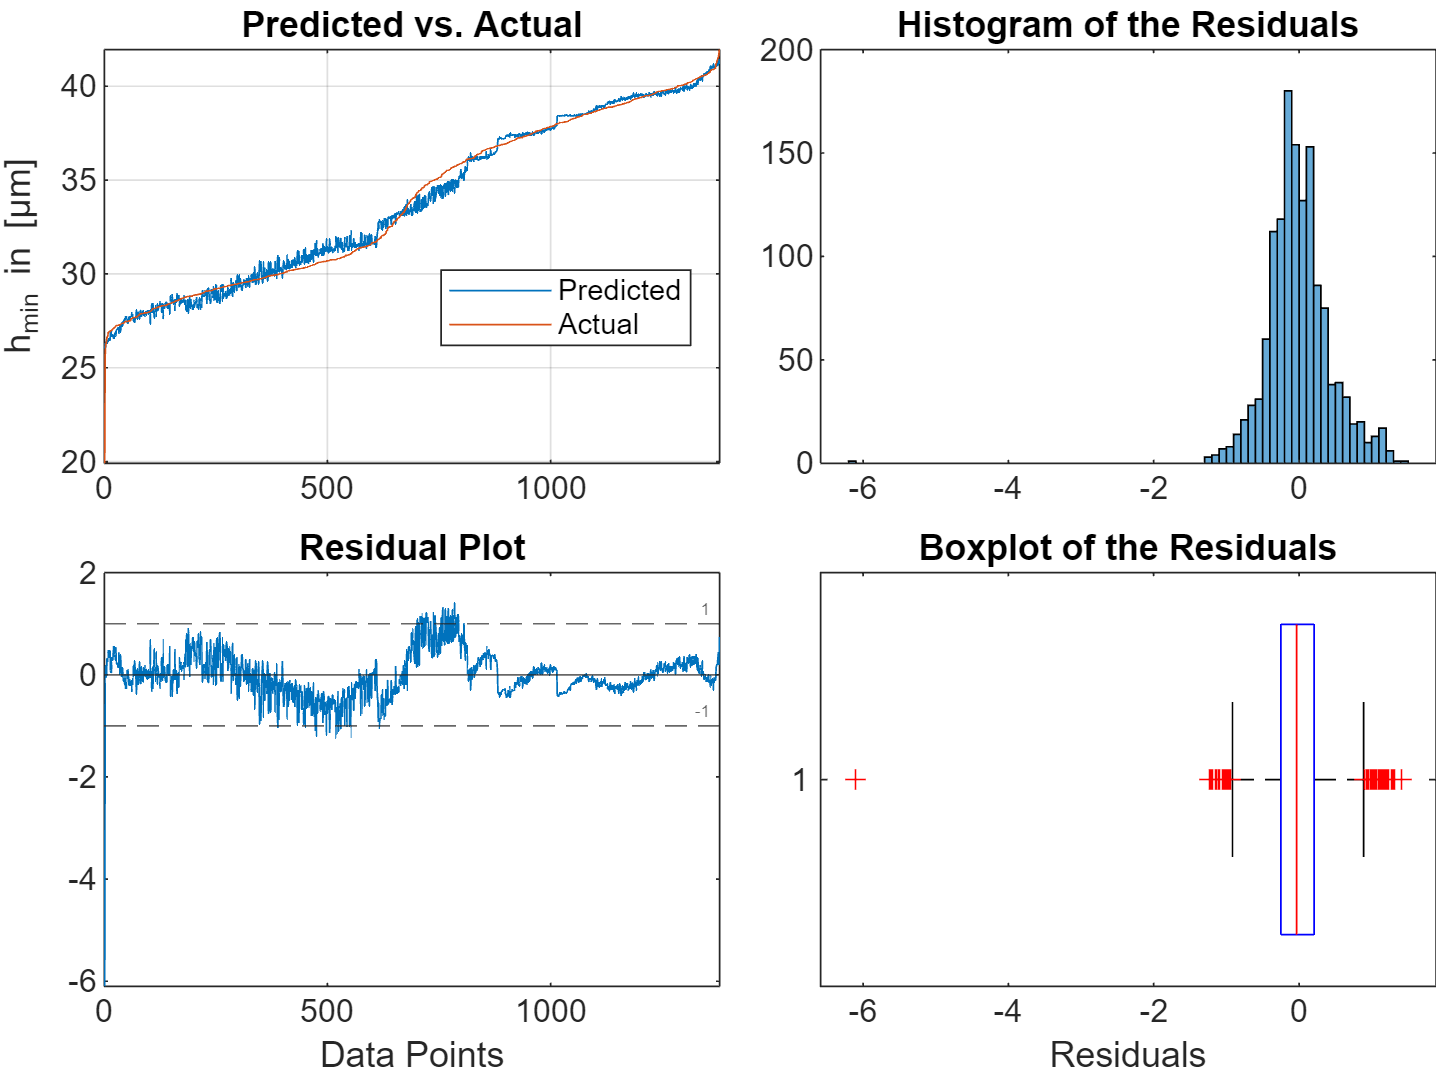

Number of Sensors: 2


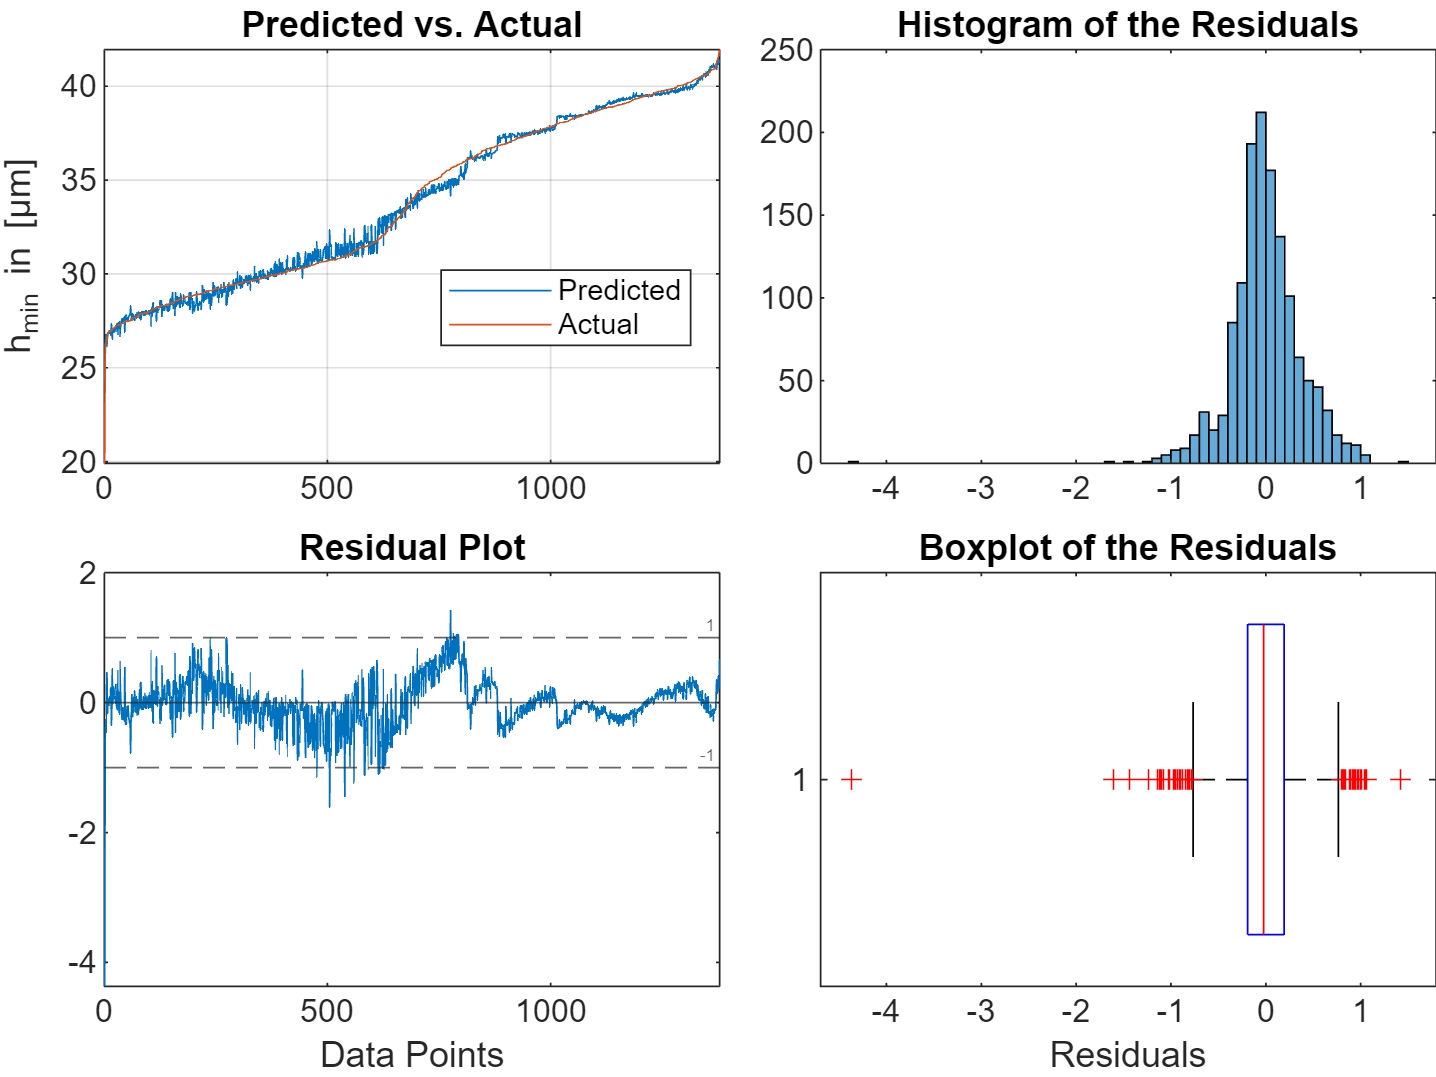

Number of Sensors: 3


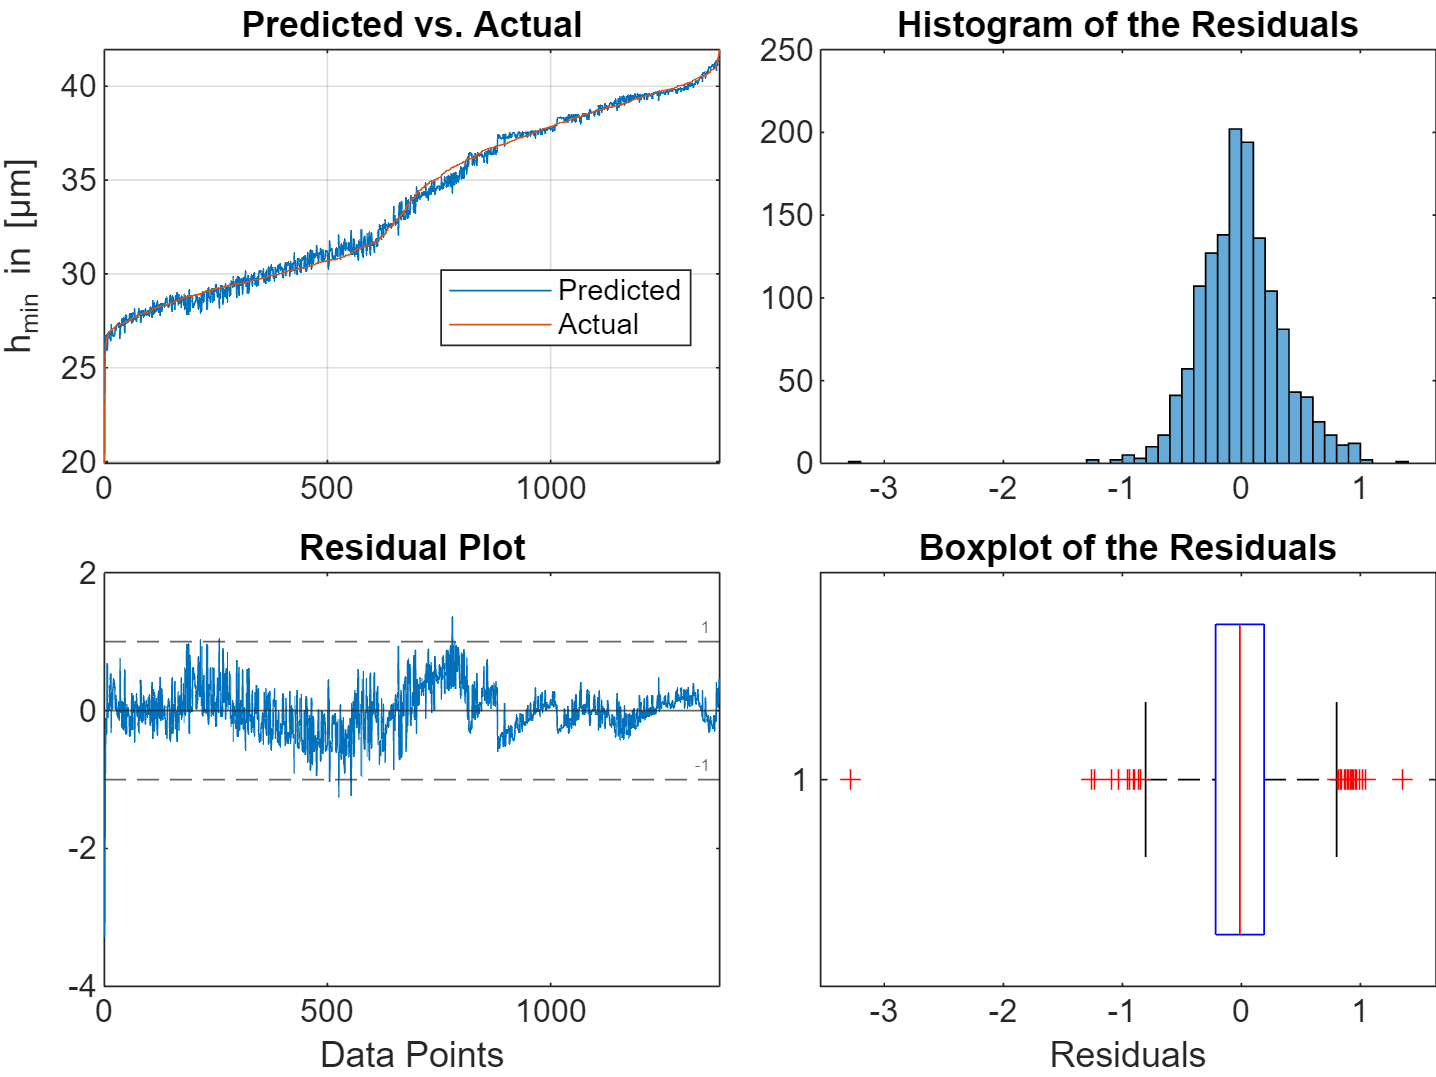

Number of Sensors: 4


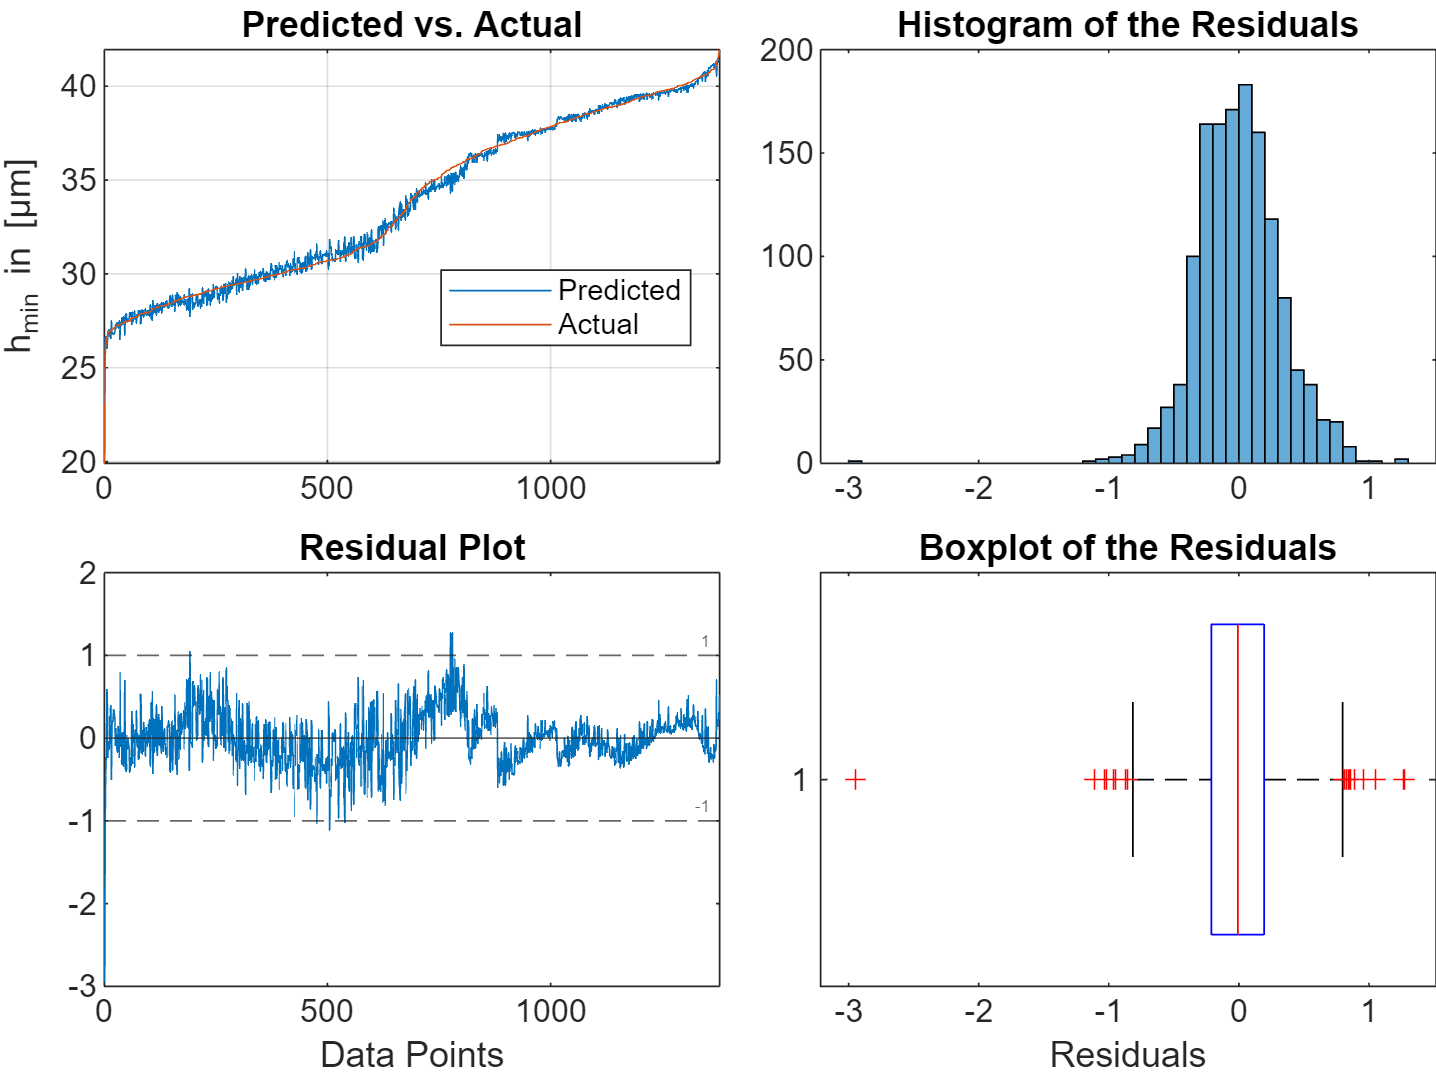

Number of Sensors: 5


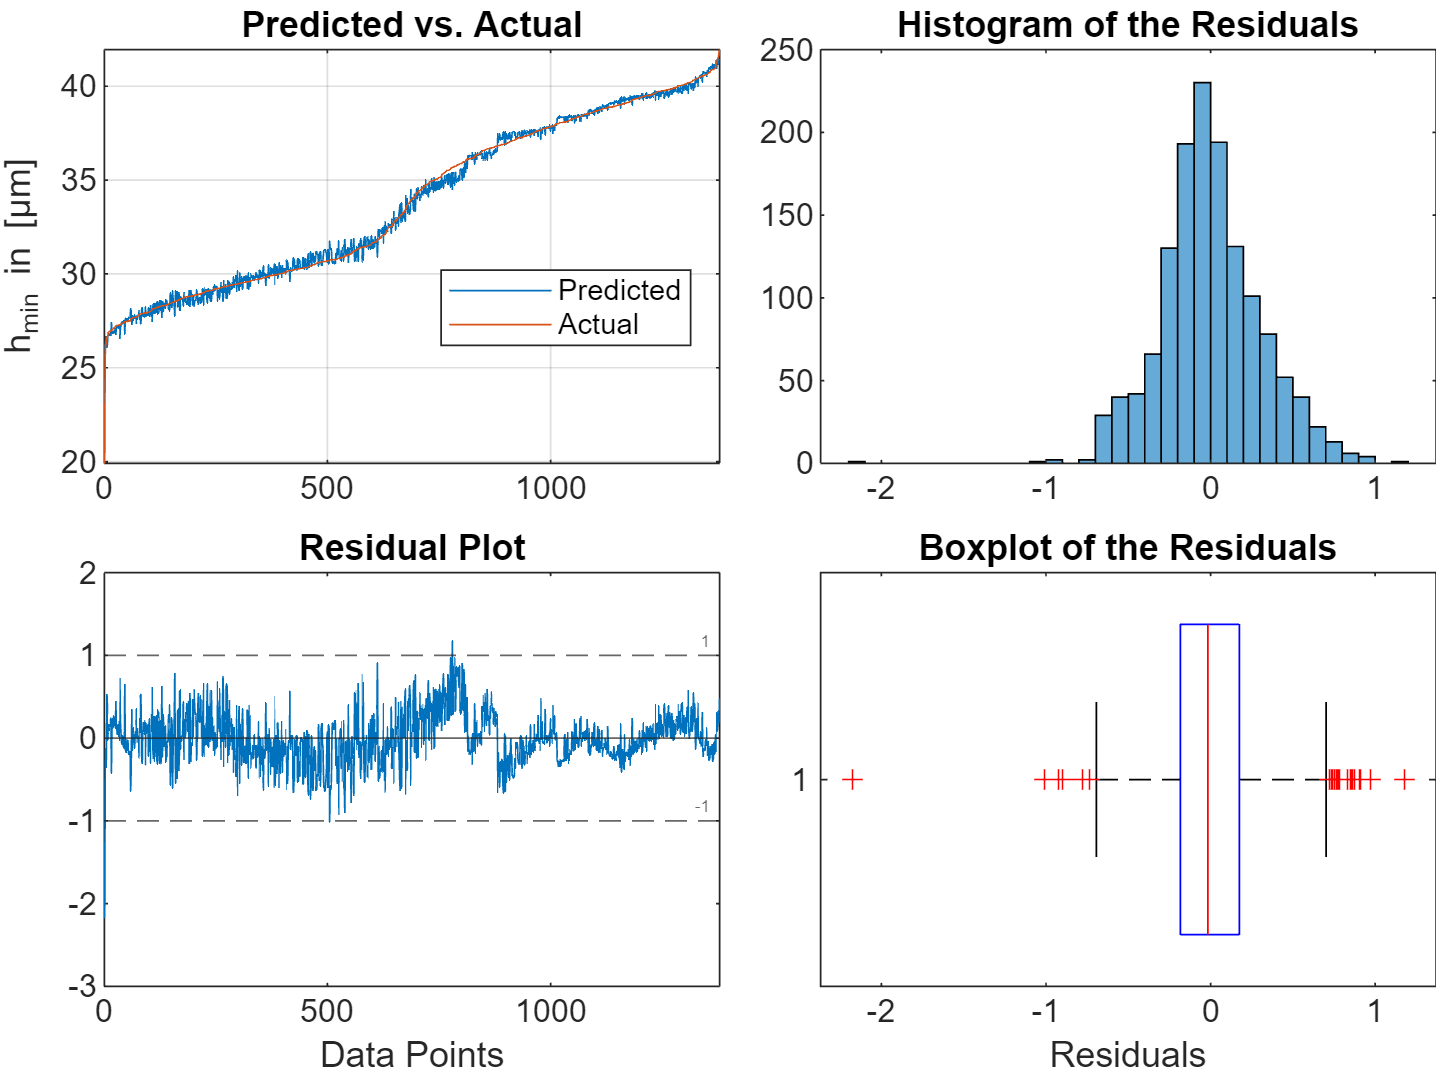

Number of Sensors: 6


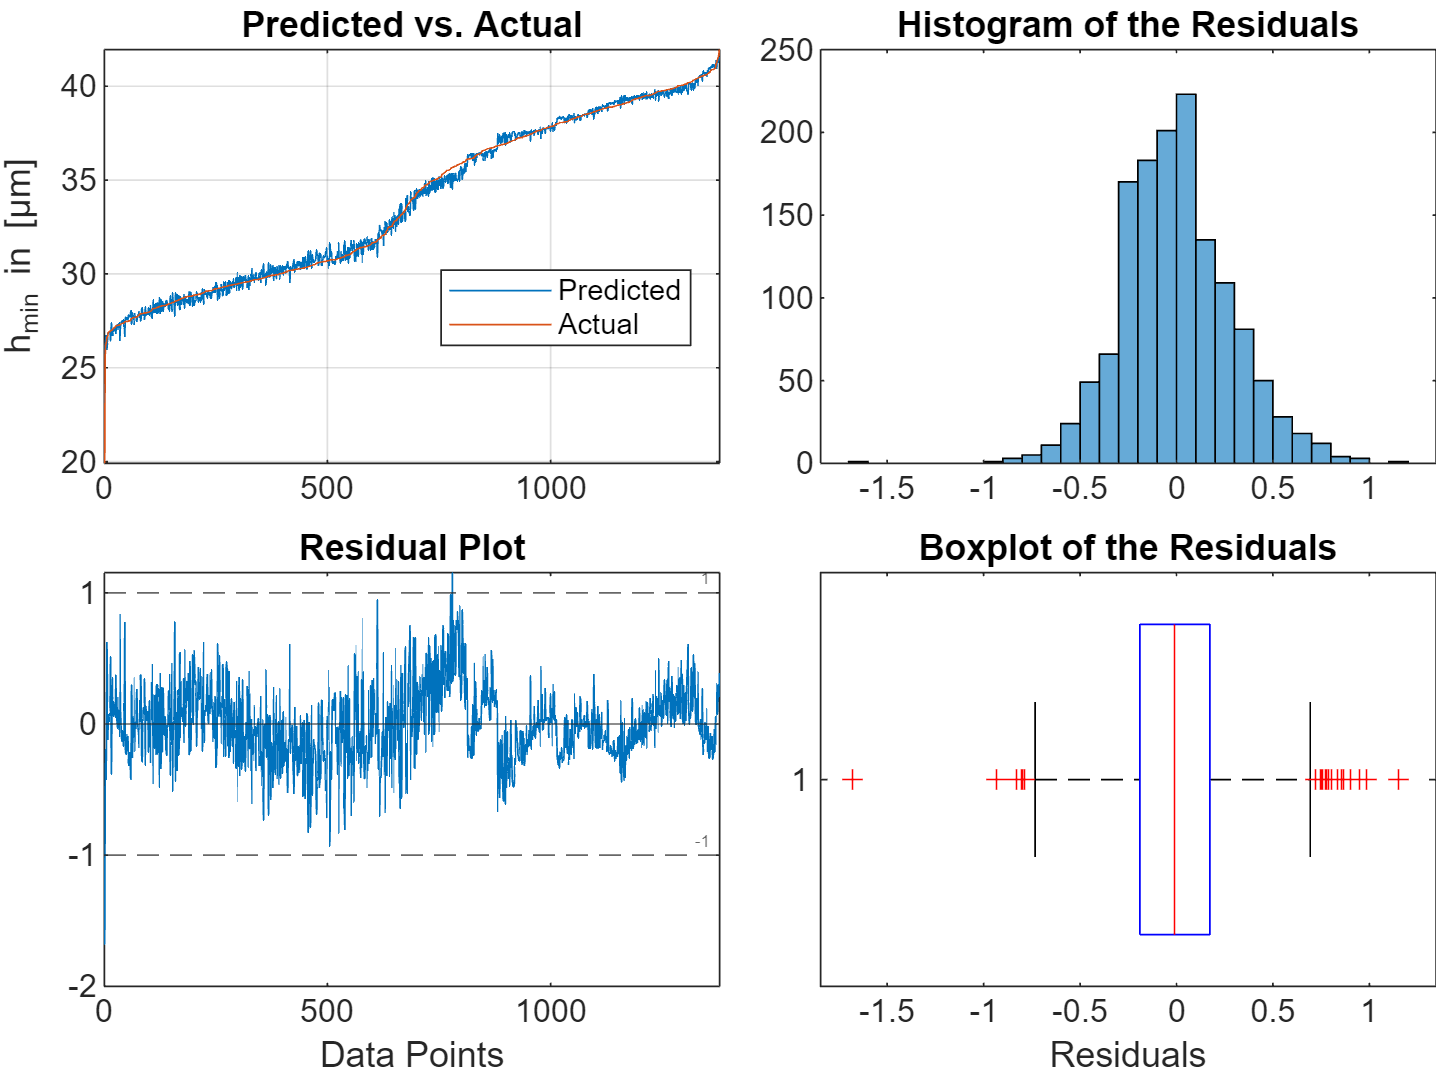

Number of Sensors: 7


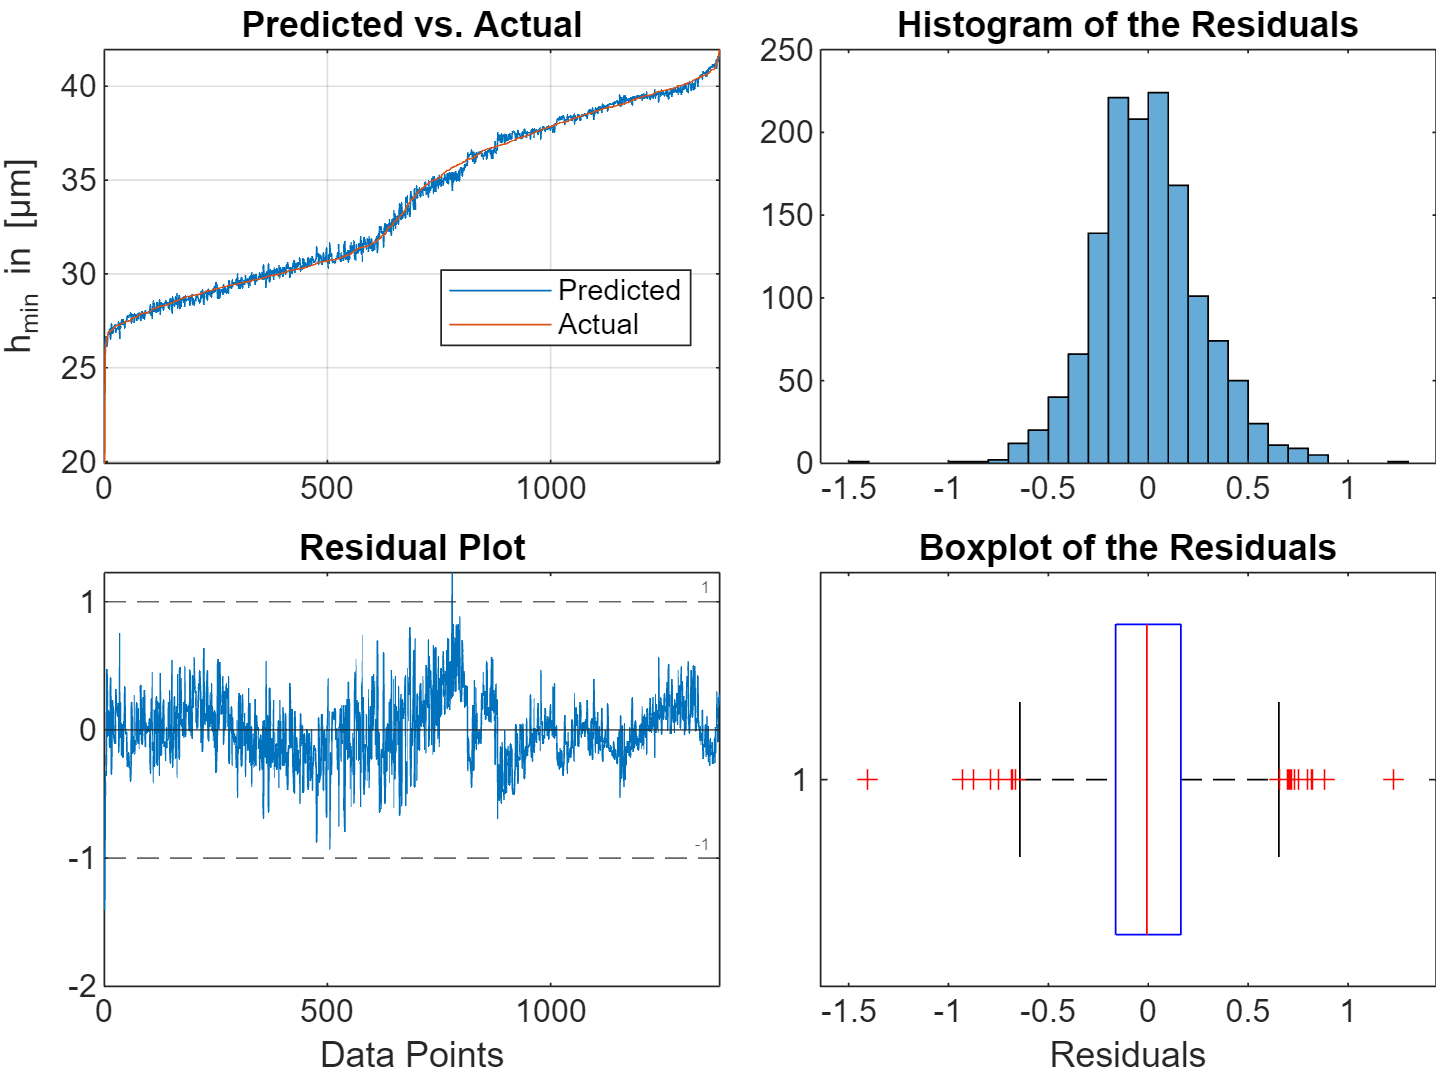

Number of Sensors: 8


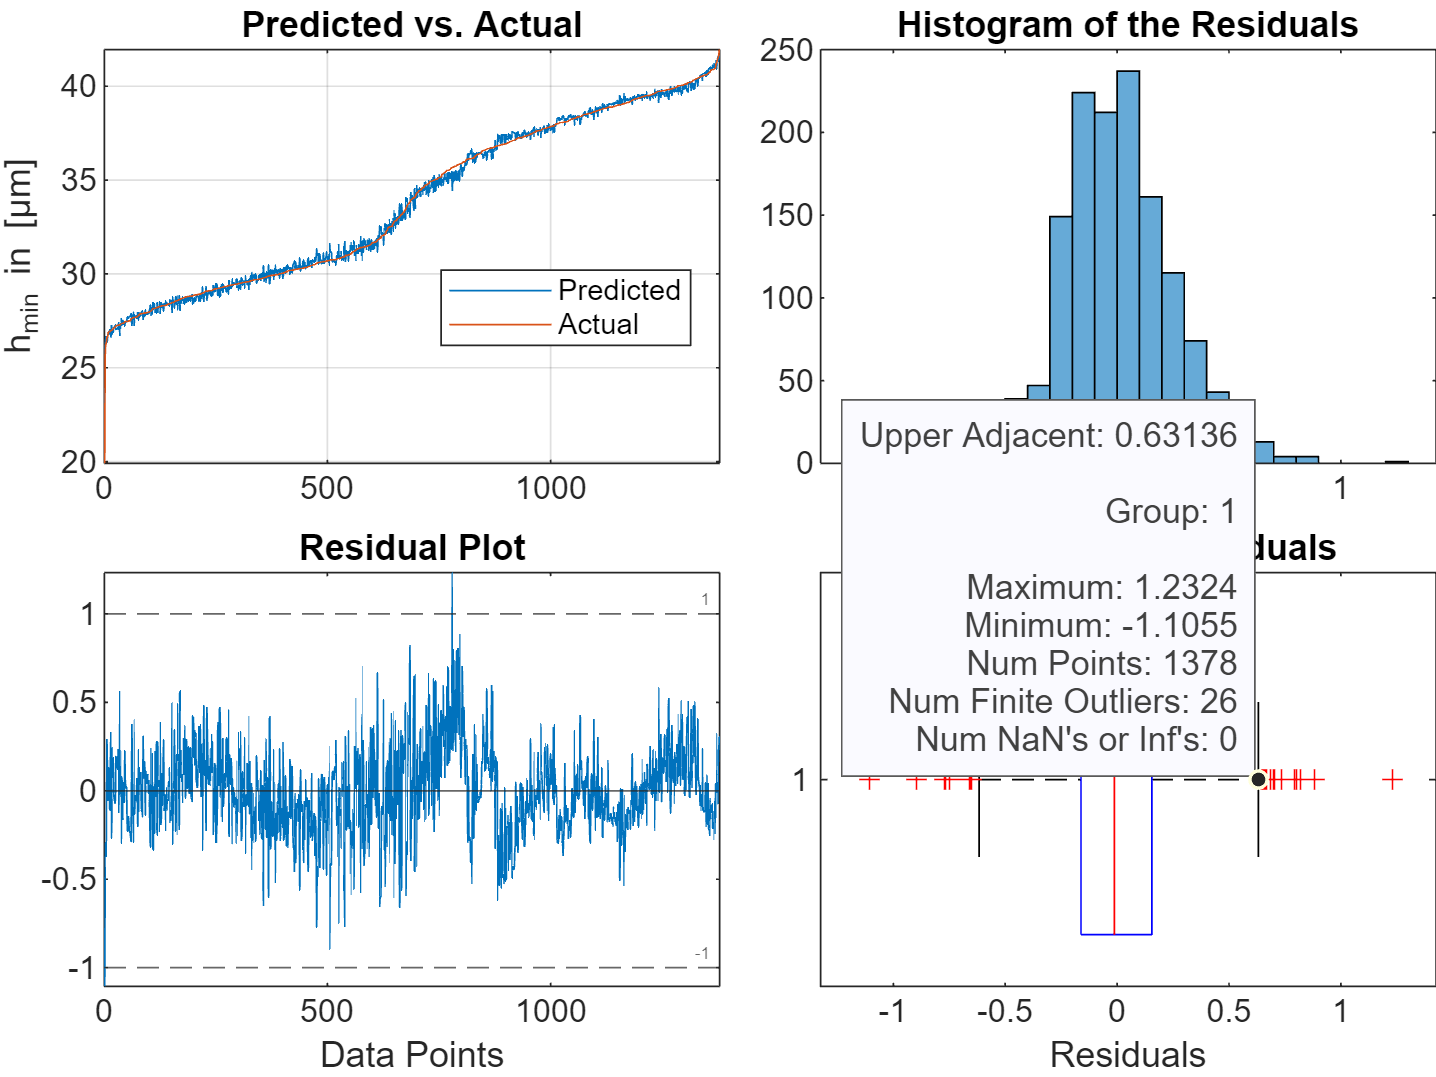

Number of Sensors: 9


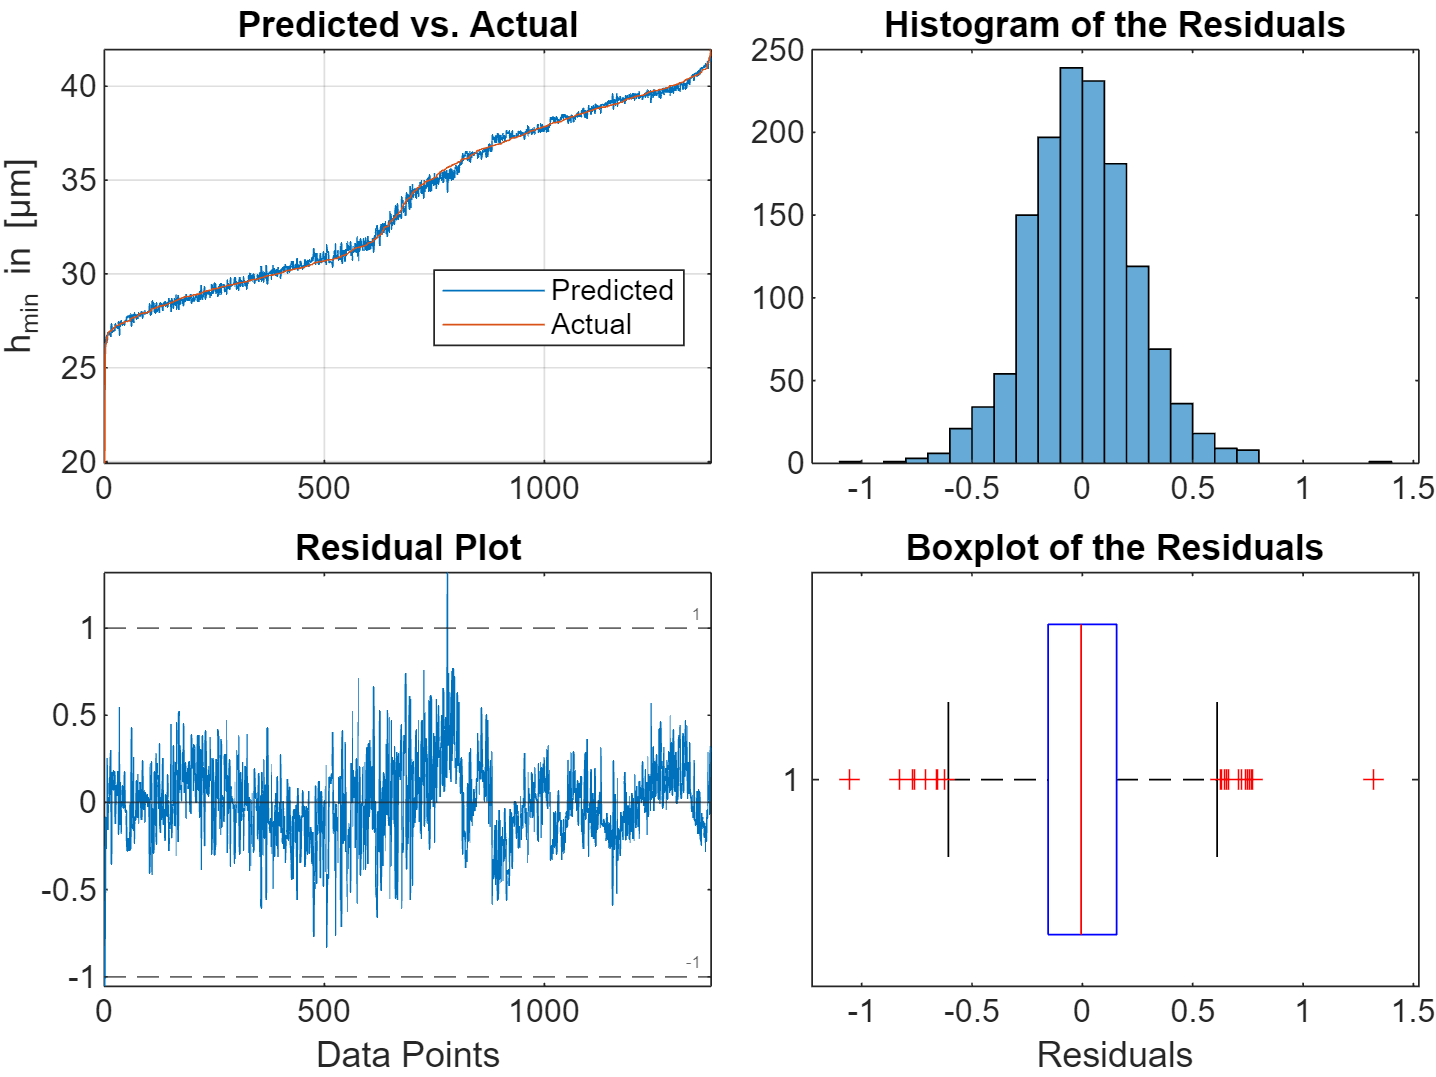

Number of Sensors: 10


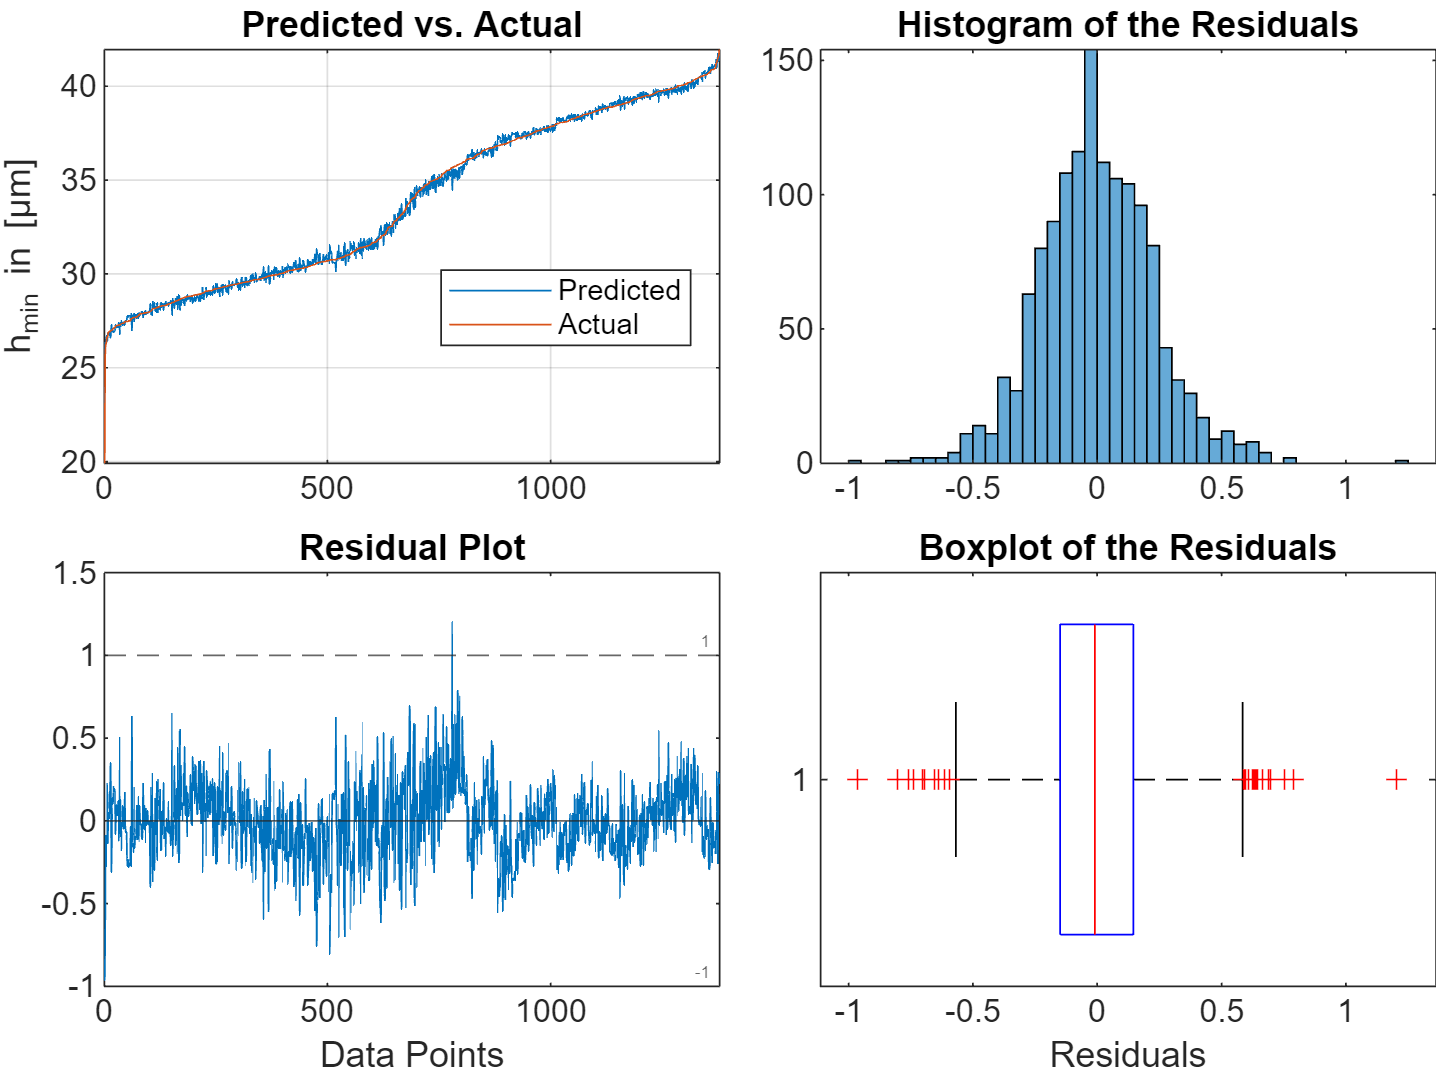

Number of Sensors: 11


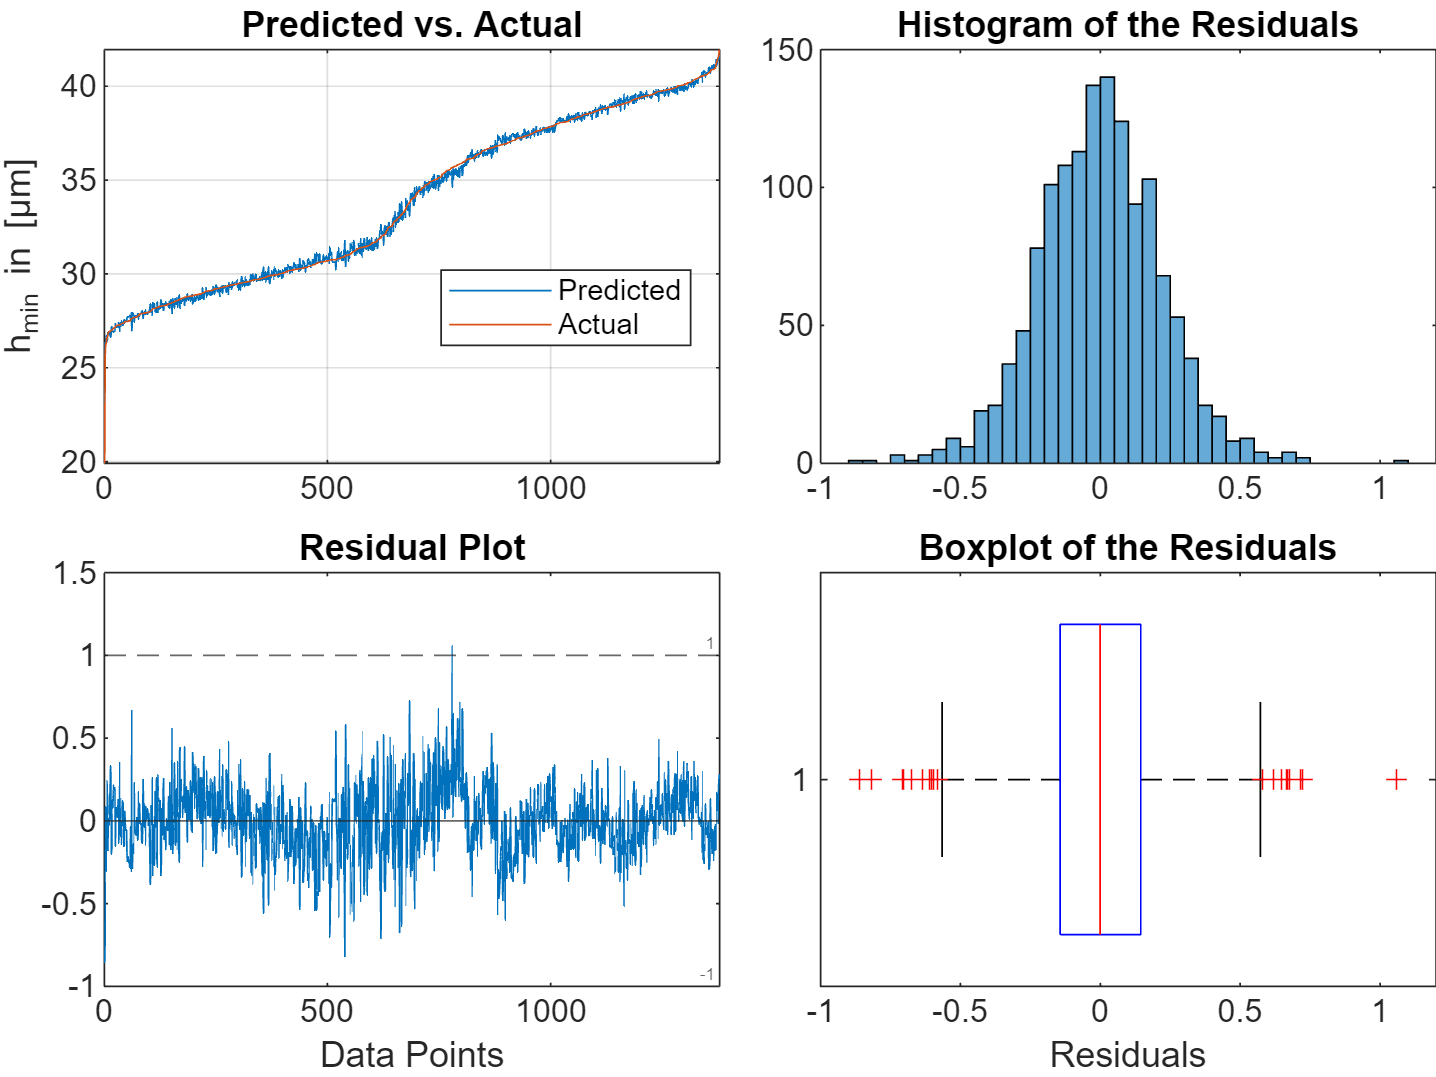

Number of Sensors: 12


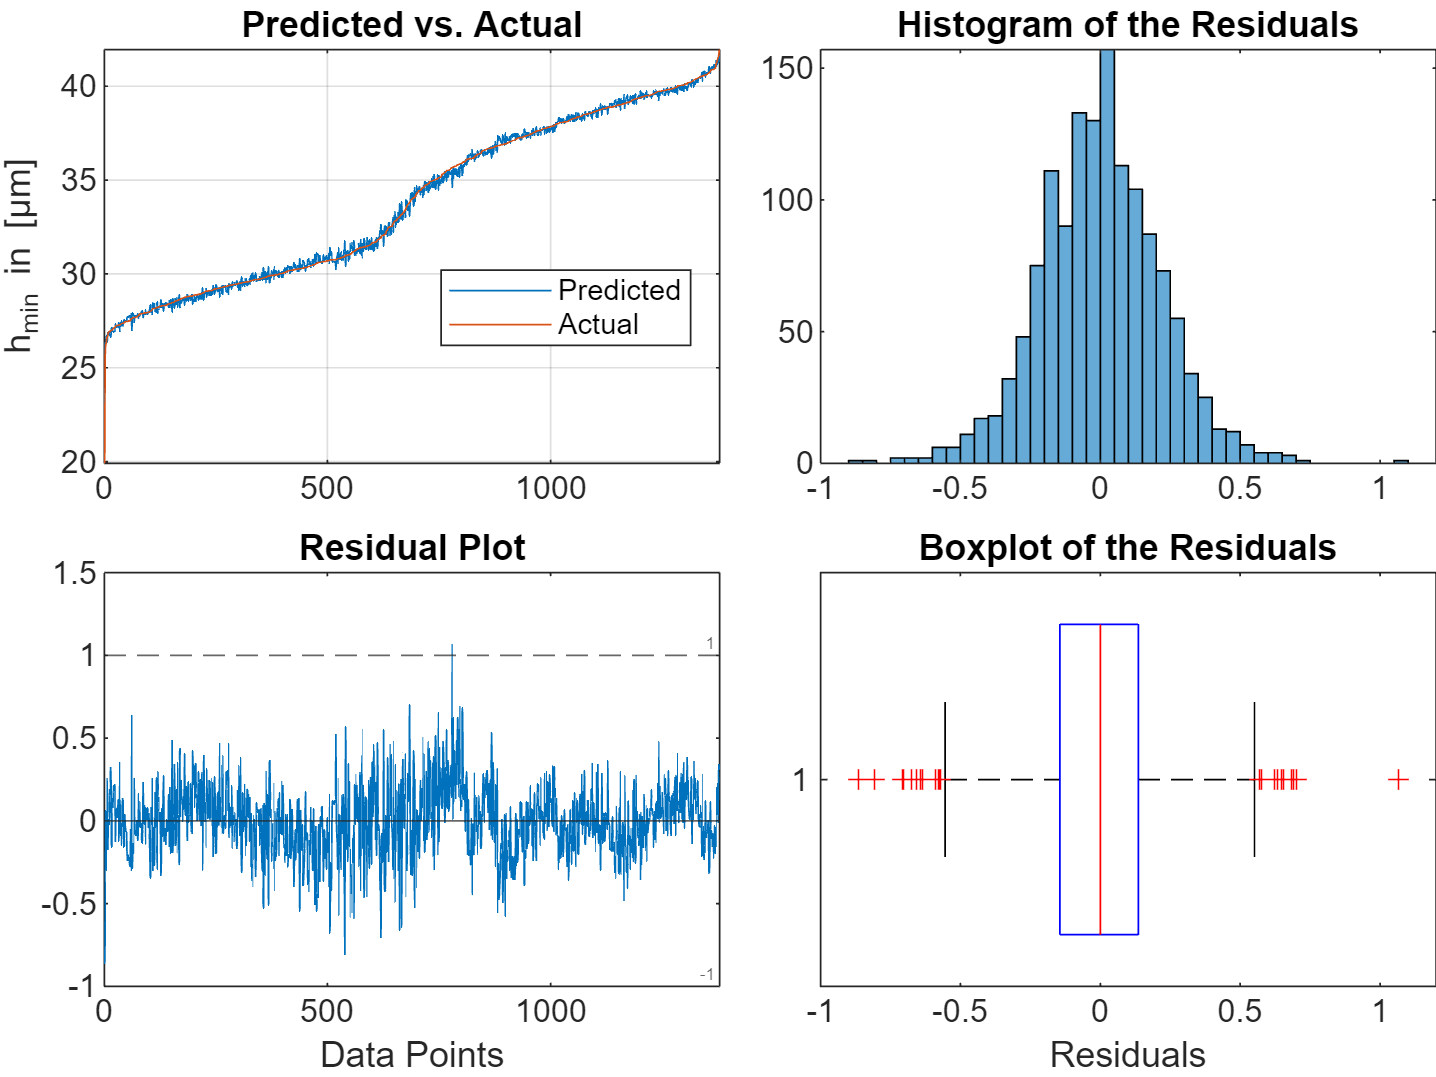

Number of Sensors: 13


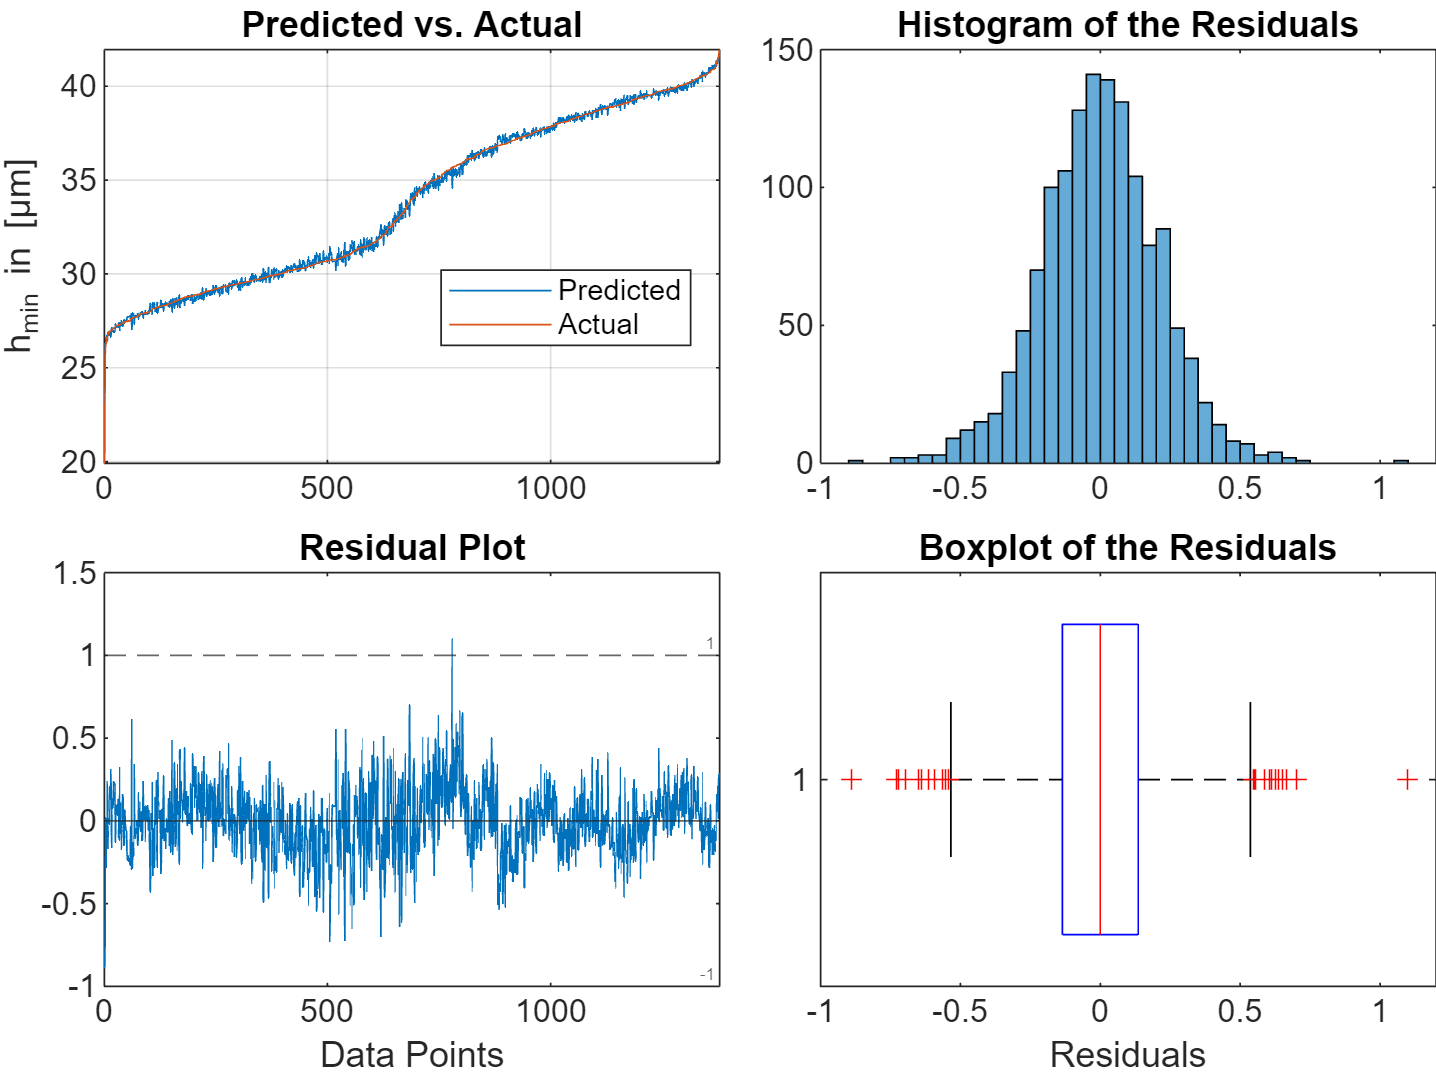

%load 'Stage 6 Regression Second Try'\'saved data'\combi_tbl.mat
%load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat
%load 'Stage 6 Regression Second Try'\'saved data'\'true values'\h_min_sorted.mat

for i = 1:numel(bestSubset)
    disp("Number of Sensors: "+i)
    h = bestSubset(i).h_min_fit;
    figure
    
    fig = tiledlayout(2,2,"TileSpacing","compact","Padding","tight");
    %title(fig,"Predicted vs. Actual")

    ax1 = nexttile; % predicted vs. actual
    plot(1:length(h),h)
    hold on, grid on
    plot(1:length(h),h_min_sorted{:,:})
    %plot(1:length(h),combi_tbl.h_min_lim)
    hold off
    ylabel("h_{min} in [μm]")
    legend("Predicted","Actual","Location","best")
    title(ax1,"Predicted vs. Actual")

    ax3 = nexttile; % histogram of the residuals
    histogram(bestSubset(i).Residuals);
    title("Histogram of the Residuals")
    
    ax2 = nexttile; % residual plot
    plot(1:length(h),bestSubset(i).Residuals)
    title(ax2,"Residual Plot")
    yline(0),xlim(ax2,[0,length(h)+1])
    yline([-1,1],'--',["-1","1"],'FontSize',5)
    xlabel("Data Points"),xlim(ax1,[0,length(h)+1])

    ax4 = nexttile;
    boxplot(bestSubset(i).Residuals,"Orientation","horizontal")
    title(ax4,"Boxplot of the Residuals")
    xlabel("Residuals")

    linkaxes([ax1 ax2],'x');
    linkaxes([ax3 ax4],'x'); 
end

# Best subset selection with stepwiselm 

fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\Stage 6 Regression Second Try\saved data");
addpath(fpath,dpath);
load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat
load 'Stage 6 Regression Second Try'\'saved data'\'true values'\h_min_sorted.mat
load 'Stage 6 Regression Second Try'\'saved data'\regression\Tp_14_sorted.mat
load 'Stage 6 Regression Second Try'\'saved data'\regression\Tv_13_sorted.mat

基于bestSubset得出的sensor combinations, 用 stepwiselm() 重新拟合模型，并观察是否存在显著改进

**bestSubset**: num_sensors, combination, Tv_model, Tv_MSE, Tp_14_sorted_fitted, Tp_model, Tp_MSE, h_min_fit, Residuals, h_MSE

for i = 1:numel(bestSubset)
    bestSubset_stp(i).num_sensors = i;
    idx = bestSubset(i).combination;
    bestSubset_stp(i).combination = idx;

    % train cross-validated stepwiselm to predict T_{max}
    [trained_mdl,~,vMSE] = train_sTv_model(Tv_13_sorted,idx);
    bestSubset_stp(i).Tv_model = trained_mdl;
    bestSubset_stp(i).Tv_MSE = vMSE;

    % predict T_max with the trained model
    yfit = trained_mdl.predictFcn(Tv_13_sorted(:,1:end-1));
    yfit = array2table(yfit,"VariableNames","T_value");
    Tp_14_sorted(:,"T_value") = yfit;
    bestSubset_stp(i).Tp_14_sorted_fitted = Tp_14_sorted;

    % train cross-validated quadratic linear model to predict beta_{T_{max}}
    % note: may need to perform Ridge regression
    [trained_mdl,~,vMSE] = train_sTp_model(Tp_14_sorted,idx);
    bestSubset_stp(i).Tp_model = trained_mdl;
    bestSubset_stp(i).Tp_MSE = vMSE;

end

% Calculate h_min_fit, h_MSE, Residuals
h_min_true = h_min_sorted{:,:};
for i = 1:numel(bestSubset_stp)
    mdl = bestSubset_stp(i).Tp_model;
    Tp14_tbl = bestSubset_stp(i).Tp_14_sorted_fitted;
    yfit = mdl.predictFcn(Tp14_tbl(:,1:end-1)); % predicted beta_Tmax
    
    h_min_fit = beta_to_hmin(yfit,120,1.6667,0.25);
    bestSubset_stp(i).h_min_fit = h_min_fit; % h_min_fit

    err = h_min_true - h_min_fit; % h_min_true的顺序对应T_max_positions_sorted的顺序
    bestSubset_stp(i).Residuals = err; % Residuals
    MSE = sum(err.^2)/length(h_min_fit); 
    bestSubset_stp(i).h_MSE = MSE; % h_MSE
end
bestSubset_stp

bestSubset_stp = 1×13 struct array with fields:
    num_sensors
    combination
    Tv_model
    Tv_MSE
    Tp_14_sorted_fitted
    Tp_model
    Tp_MSE
    h_min_fit
    Residuals
    h_MSE


通过 h_MSE 对比是否有显著改进：

load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset_stp.mat
load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat
load 'Stage 6 Regression Second Try'\'saved data'\'true values'\h_min_sorted.mat

h_MSE = zeros(1,numel(bestSubset)); % column vector
for i = 1:numel(bestSubset)
    h_MSE(i) = bestSubset(i).h_MSE;
end

h_MSE_stp = zeros(1,numel(bestSubset_stp)); % column vector
for i = 1:numel(bestSubset_stp)
    h_MSE_stp(i) = bestSubset_stp(i).h_MSE;
end

h_MSE - h_MSE_stp

ans =    -0.0002         0         0   -0.0001   -0.0002   -0.0003   -0.0005   -0.0003   -0.0004   -0.0008   -0.0009   -0.0008   -0.0011


sqrt(h_MSE)-sqrt(h_MSE_stp)

ans =    -0.0002         0         0   -0.0001   -0.0003   -0.0005   -0.0010   -0.0006   -0.0008   -0.0017   -0.0020   -0.0019   -0.0025


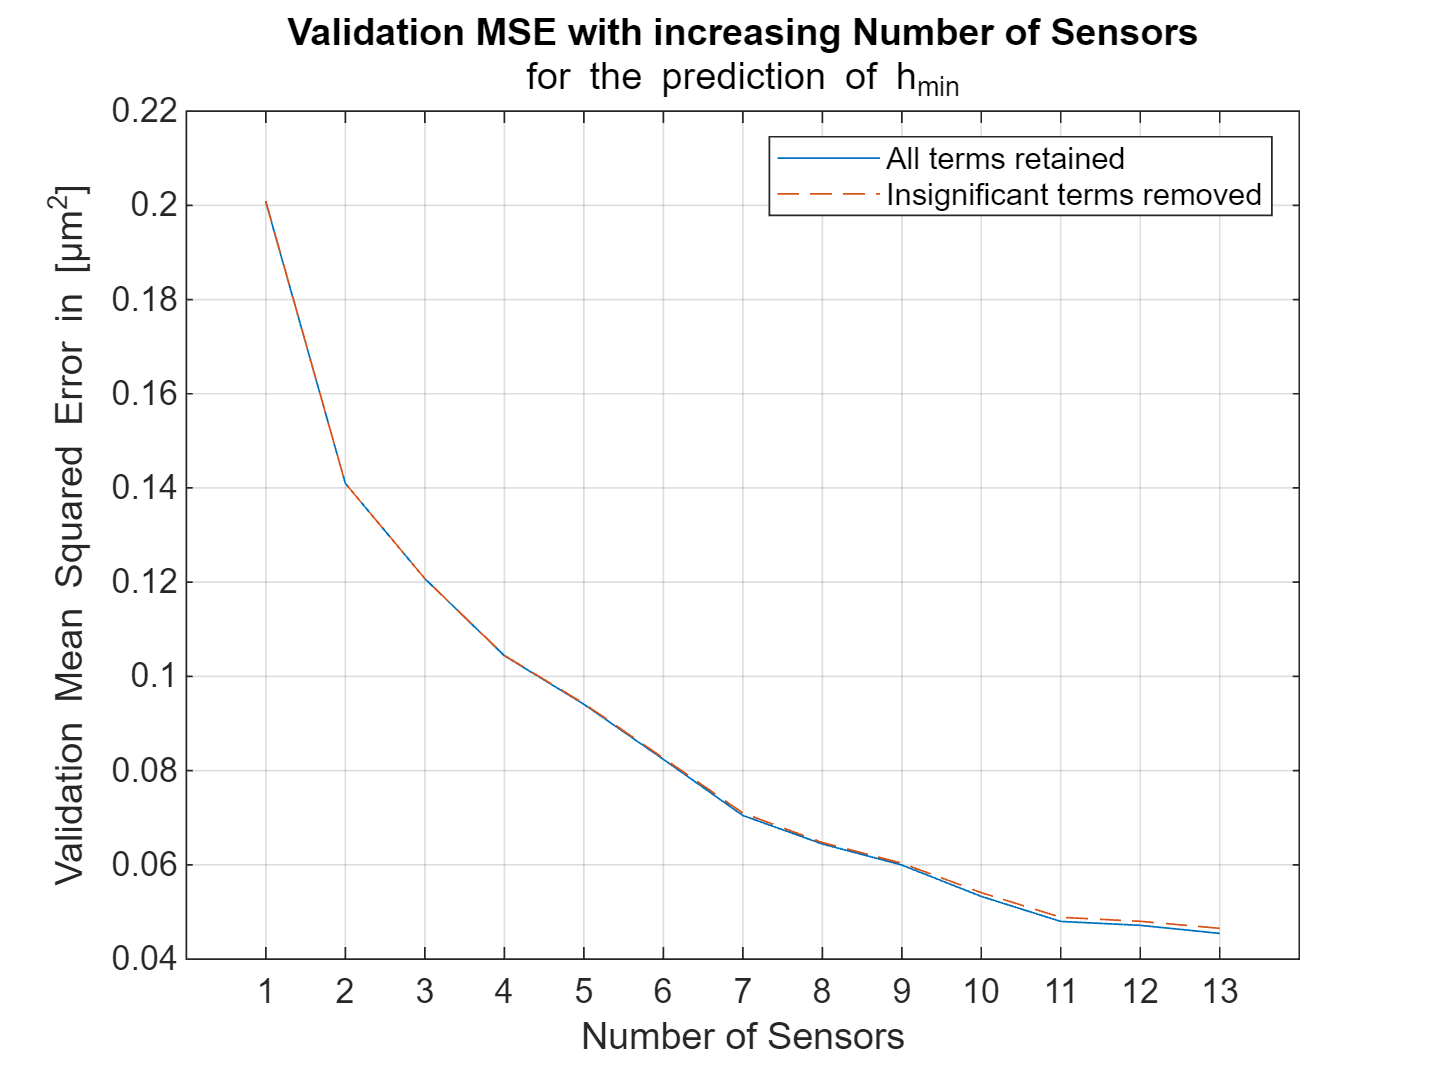

% 结论：linear quadratic model has consistently better accuracy

% plot h_MSE
figure
plot(1:13,h_MSE)
grid on, hold on
plot(1:13,h_MSE_stp,'--')
hold off
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Validation Mean Squared Error in [{μm}^2]")
title("Validation MSE with increasing Number of Sensors",...
    "for the prediction of h_{min}")
legend("All terms retained","Insignificant terms removed")

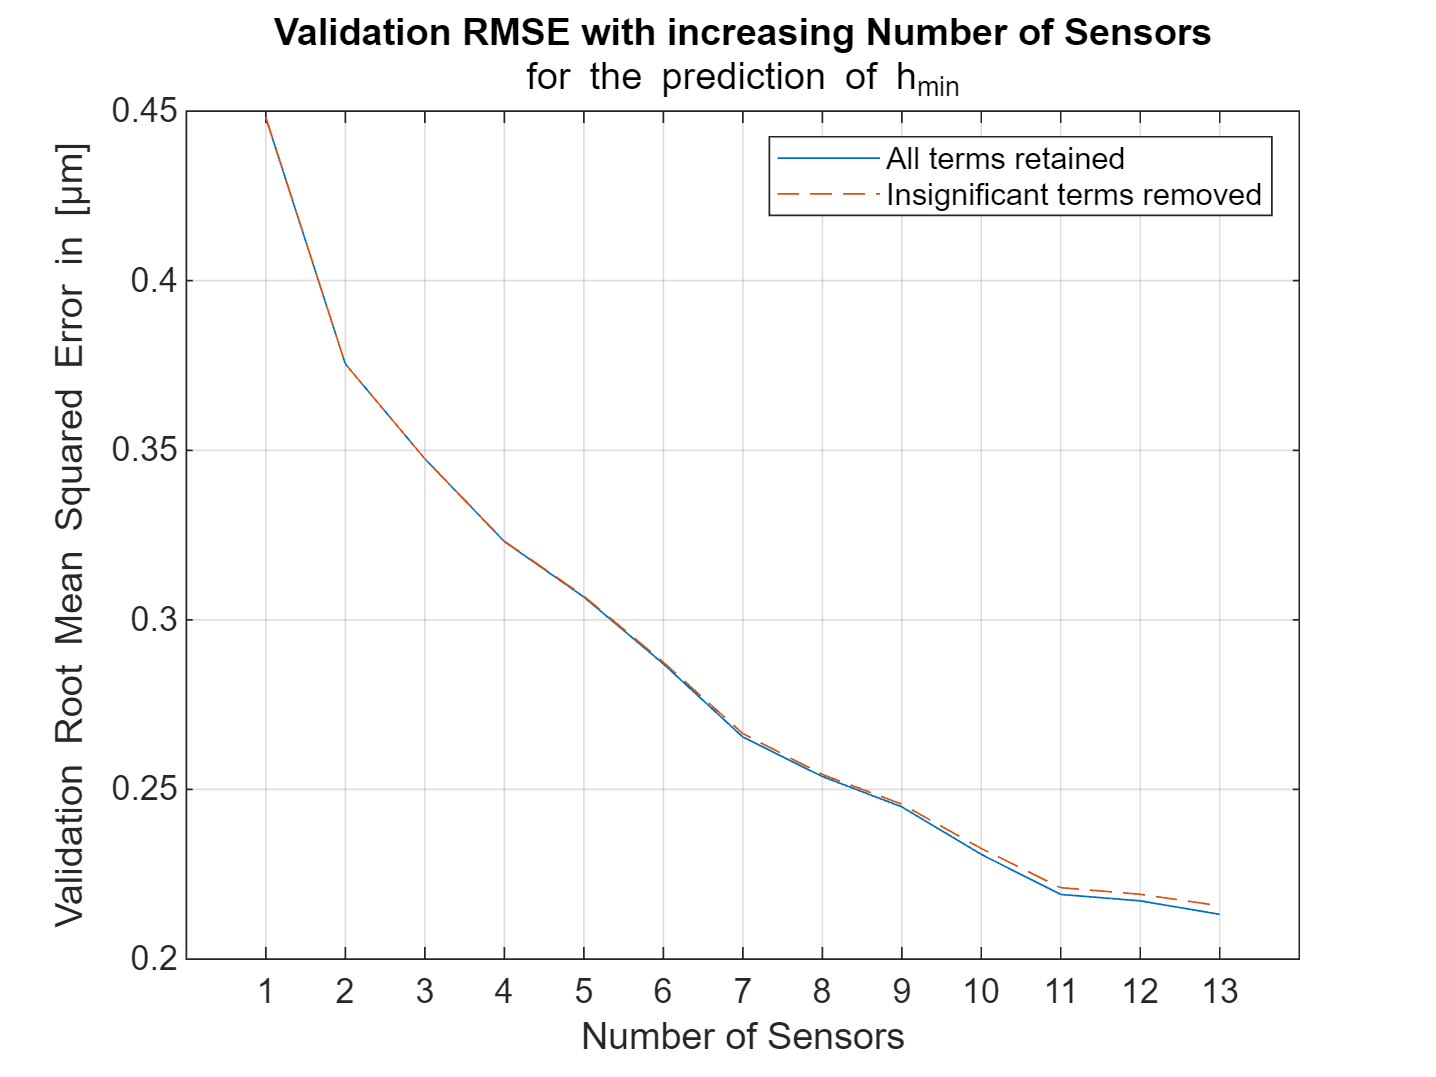


% plot h_RMSE
figure
plot(1:13,sqrt(h_MSE))
grid on, hold on
plot(1:13,sqrt(h_MSE_stp),'--')
hold off
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Validation Root Mean Squared Error in [{μm}]")
title("Validation RMSE with increasing Number of Sensors",...
    "for the prediction of h_{min}")
legend("All terms retained","Insignificant terms removed")

# Best subset selection with fitlm(...,'interactions') 

%fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
%dpath = genpath("C:\Users\regen\Documents\MATLAB\Stage 6 Regression Second Try\saved data");
%addpath(fpath,dpath);
%load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat
%load 'Stage 6 Regression Second Try'\'saved data'\'true values'\h_min_sorted.mat
%load 'Stage 6 Regression Second Try'\'saved data'\regression\Tp_14_sorted.mat
%load 'Stage 6 Regression Second Try'\'saved data'\regression\Tv_13_sorted.mat

for i = 1:13
    C = nchoosek(1:13,i); % 13选 i, 每一行表示一种组合
    bestSubset_int(i).num_sensors = i;
    
    for j = 1:height(C) % loop through every possible combination for i kept sensors
        idx = C(j,:);
        tempStruct(j).combination = idx;

        % train cross-validated quadratic linear model to predict T_{max}
        [trained_mdl,~,vMSE] = train_inTv_model(Tv_13_sorted,idx);
        tempStruct(j).Tv_model = trained_mdl;
        tempStruct(j).Tv_MSE = vMSE;

        % predict T_max with the trained model
        yfit = trained_mdl.predictFcn(Tv_13_sorted(:,1:end-1));
        yfit = array2table(yfit,"VariableNames","T_value");
        Tp_14_sorted(:,"T_value") = yfit;
        tempStruct(j).Tp_14_sorted_fitted = Tp_14_sorted;

        % train cross-validated quadratic linear model to predict beta_{T_{max}}
        % note: may need to perform Ridge regression
        [trained_mdl,~,vMSE] = train_inTp_model(Tp_14_sorted,idx);
        tempStruct(j).Tp_model = trained_mdl;
        tempStruct(j).Tp_MSE = vMSE;
        
    end

    % select the sensor combination that produces the best prediction of T_max position
    Tp_MSE = zeros(height(C),1);
    for j = 1:height(C)
        Tp_MSE(j) = tempStruct(j).Tp_MSE;
    end
    [~,minIdx] = min(Tp_MSE);

    % 将选中的行填入bestSubset(i)
    bestSubset_int(i).combination = tempStruct(minIdx).combination;
    bestSubset_int(i).Tv_model = tempStruct(minIdx).Tv_model;
    bestSubset_int(i).Tv_MSE = tempStruct(minIdx).Tv_MSE;
    bestSubset_int(i).Tp_14_sorted_fitted = tempStruct(minIdx).Tp_14_sorted_fitted;
    bestSubset_int(i).Tp_model = tempStruct(minIdx).Tp_model;
    bestSubset_int(i).Tp_MSE = tempStruct(minIdx).Tp_MSE;

end

% Calculate h_min_fit, h_MSE, Residuals
h_min_true = h_min_sorted{:,:};
for i = 1:numel(bestSubset_int)
    mdl = bestSubset_int(i).Tp_model;
    Tp14_tbl = bestSubset_int(i).Tp_14_sorted_fitted;
    yfit = mdl.predictFcn(Tp14_tbl(:,1:end-1)); % predicted beta_Tmax
    
    h_min_fit = beta_to_hmin(yfit,120,1.6667,0.25);
    bestSubset_int(i).h_min_fit = h_min_fit; % h_min_fit

    err = h_min_true - h_min_fit; % h_min_true的顺序对应T_max_positions_sorted的顺序
    bestSubset_int(i).Residuals = err; % Residuals
    MSE = sum(err.^2)/length(h_min_fit); 
    bestSubset_int(i).h_MSE = MSE; % h_MSE
end
bestSubset_int

bestSubset_int = 1×13 struct array with fields:
    num_sensors
    combination
    Tv_model
    Tv_MSE
    Tp_14_sorted_fitted
    Tp_model
    Tp_MSE
    h_min_fit
    Residuals
    h_MSE


%load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset_int.mat
%load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat

h_MSE = zeros(1,numel(bestSubset)); % column vector
for i = 1:numel(bestSubset)
    h_MSE(i) = bestSubset(i).h_MSE;
end

h_MSE_int = zeros(1,numel(bestSubset_int)); % column vector
for i = 1:numel(bestSubset_int)
    h_MSE_int(i) = bestSubset_int(i).h_MSE;
end

h_MSE - h_MSE_int % consistently < 0, h_MSE更好

ans =    -0.0251   -0.0084   -0.0075   -0.0021   -0.0039   -0.0032   -0.0045   -0.0030   -0.0037   -0.0030   -0.0030   -0.0023   -0.0022


sqrt(h_MSE) - sqrt(h_MSE_int)

ans =    -0.0272   -0.0110   -0.0107   -0.0032   -0.0064   -0.0054   -0.0084   -0.0059   -0.0074   -0.0064   -0.0068   -0.0052   -0.0052


min(sqrt(h_MSE) - sqrt(h_MSE_int)) % 最大差距：0.0272

ans = -0.0272